clc;
clear;
close all;


smiles="C1CCCCC1"

smiles = "C1CCCCC1"


xyz_tb_1=readmatrix("E:\VScode\Proj_Molecular3D_V1\File\Output\"+smiles+"\XYZ_1.csv")

xyz_tb_1 =          0         0         0
         0         0    1.5080
    1.4215         0    2.0114
    1.4215         0    3.5194
    2.8430         0    4.0228
   -1.4215         0   -0.5034
    0.5152   -0.8923   -0.3649
    0.5152    0.8923   -0.3649
   -0.5152   -0.8923    1.8728
   -0.5152    0.8923    1.8728


xyz_tb_2=readmatrix("E:\VScode\Proj_Molecular3D_V1\File\Output\"+smiles+"\XYZ_2.csv")

xyz_tb_2 =          0         0         0
         0         0    1.5080
   -1.4140   -0.1458    2.0114
   -2.3396    0.6872    1.1607
   -2.4833    0.0505   -0.1987
   -1.2348   -0.7042   -0.5034
    0.8895   -0.5199   -0.3649
    0.0054    1.0303   -0.3649
    0.4209    0.9404    1.8728
    0.6039   -0.8347    1.8728


xyz_tb_3=readmatrix("E:\VScode\Proj_Molecular3D_V1\File\Output\"+smiles+"\XYZ_3.csv")

xyz_tb_3 =          0         0         0
         0         0    1.5080
    1.3866    0.3132    2.0114
    2.3923   -0.5394    1.2795
    1.6813   -1.3933    0.2600
    0.3850   -1.3684   -0.5034
    0.7194    0.7375   -0.3649
   -0.9984    0.2543   -0.3649
   -0.3059   -0.9838    1.8728
   -0.6991    0.7568    1.8728



bond_tb=readtable("../Output/"+smiles+"/BondTable.csv")

bond_tb = 12×3 table
    Seq1    Seq2    BondSym
    ____    ____    _______

     0       1       {'-'} 
     0       5       {'-'} 
     1       0       {'-'} 
     1       2       {'-'} 
     2       1       {'-'} 
     2       3       {'-'} 
     3       2       {'-'} 
     3       4       {'-'} 
     4       3       {'-'} 
     4       5       {'-'} 
     5       4       {'-'} 
     5       0       {'-'} 


nh_tb=readtable("E:\VScode\Proj_Molecular3D_V1\File\Output\"+smiles+"\MNodeTable.csv")

nh_tb = 6×9 table
    Seq    Element    IsAroma    CCount    CHCount    NHBC    CharSym    CharVal    MType
    ___    _______    _______    ______    _______    ____    _______    _______    _____

     0      {'C'}        0         2          2        2         0          0        -1  
     1      {'C'}        0         2          2        2         0          0        -1  
     2      {'C'}        0         2          2        2         0          0        -1  
     3      {'C'}        0         2          2        2         0          0        -1  
     4      {'C'}        0         2          2        2         0          0        -1  
     5      {'C'}        0         2          2        2         0          0        -1  


adj_list=bond2adj(bond_tb,"No",nh_tb)


adj_list =

  具有 6 个条目的 dictionary (cell ⟼ cell):

    {'0'} ⟼ {[1 5 6 7]}
    {'1'} ⟼ {[0 2 8 9]}
    {'2'} ⟼ {[1 3 10 11]}
    {'3'} ⟼ {[2 4 12 13]}
    {'4'} ⟼ {[3 5 14 15]}
    {'5'} ⟼ {[0 4 16 17]}



ac=size(xyz_tb_2,1)

ac = 18

nhc=size(nh_tb,1)

nhc = 6


%big_adj_list=bond2adj(bond_tb,"Yes",nh_tb)

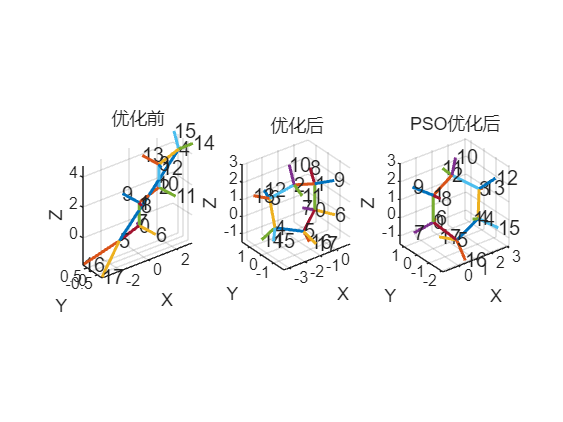

figure;
subplot(1,3,1);
moledraw(xyz_tb_1,adj_list)
title("优化前")

subplot(1,3,2);
moledraw(xyz_tb_2,adj_list)
title("优化后")

subplot(1,3,3);
moledraw(xyz_tb_3,adj_list)
title("PSO优化后")

S=strings(ac,1);
for i=1:ac
    if i<=nhc
        S(i,1)=nh_tb{i,"Element"};
    else
        S(i,1)="H";
    end
end
SXYZ=array2table([S,xyz_tb_2],"VariableNames",["Symbol","X","Y","Z"]);
writetable(SXYZ, "../Output/"+smiles+"/SXYZ.csv");

%new_bond_tb=bond_tb{:,1:2}+1;




T2=[];
for j=1:nhc
    now_parent_j=j-1;
    nb_node=adj_list({num2str(now_parent_j)});
    nb_node=sort(nb_node{:});
    nsize=size(nb_node,2);
    for i=1:nsize
        if j<nb_node(1,i)+1
            T2=[T2;j nb_node(1,i)+1];
        end
    end
end
ADJT=array2table(T2,"VariableNames",["A","B"]);
writetable(ADJT, "../Output/"+smiles+"/ADJ_AB.csv");

% val=3
% val_lim=[-val val]
% xlim(val_lim)
% ylim(val_lim)
% zlim(val_lim)

function adj_list=bond2adj(bond_tb,Hcount,nh_tb)
nhc=size(nh_tb,1);
ac=sum(nh_tb{:,"CHCount"})+nhc;
oldseq=-1;
nowarr=[];
if Hcount=="Yes"
    keys=cell(1,ac);
    values=cell(1,ac);
else
    keys=cell(1,nhc);
    values=cell(1,nhc);
end

nowhseq=nhc;
for i=1:size(bond_tb)
    nowseq=bond_tb{i,"Seq1"};
    if oldseq==nowseq
        nowarr=[nowarr,bond_tb{i,"Seq2"}];
    else
        %nowhseq=nowhseq+nowhnum;
        if i~=1
            nowhnum=nh_tb{oldseq+1,"CHCount"};
            for j=1:nowhnum
                nowarr=[nowarr,nowhseq];
                nowhseq=nowhseq+1;
            end
            nowarr=sort(nowarr);
            values{1,oldseq+1}=nowarr;
        end
        nowarr=[bond_tb{i,"Seq2"}];
        oldseq=nowseq;
        keys{1,nowseq+1}=num2str(nowseq);
    end
end
nowhnum=nh_tb{oldseq+1,"CHCount"};
for j=1:nowhnum
    nowarr=[nowarr,nowhseq];
    nowhseq=nowhseq+1;
end
nowarr=sort(nowarr);
values{1,oldseq+1}=nowarr;
% if Hcount=="Yes"
%     nownhseq=0;
%     nowhcount=0;
%     for i=(nhc+1):ac
%         keys{1,i}=i-1;
%         values{1,i}=nownhseq;
%         if nowhcount==nh_tb{nownhseq+1,"CHCount"}
%             nowhseq=nowhseq+1;
%             nowhcount=0;
%         end
%     end
% end
adj_list=dictionary(keys,values);
end